## Import the data

 
close all hidden 
clearvars hidden force
clearvars global force
[fileName, folder] = uigetfile('*.csv');
warning('off', 'MATLAB:table:ModifiedAndSavedVarnames');
dataTable = readtable(fullfile(folder, fileName),  'DecimalSeparator',',');
dataTable(1,:) = [];
fullfile(folder, fileName)

## Mark high and low values

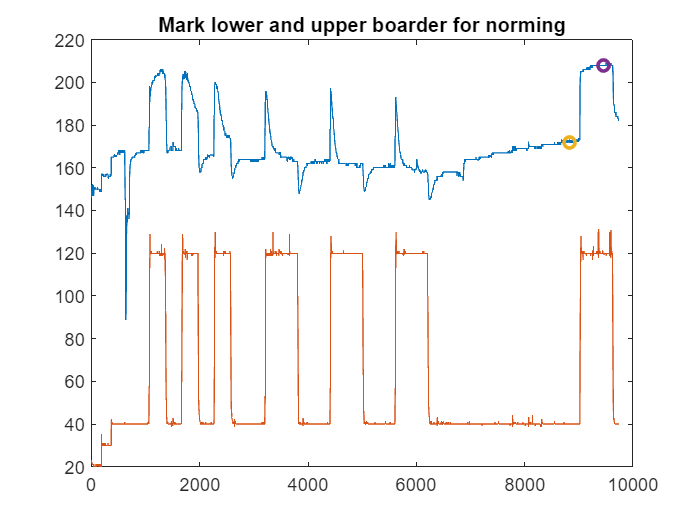

 
fig = figure;
plot(dataTable.Time, dataTable.OuterDiameter, dataTable.Time_1, dataTable.InletPressure);
for i = 1:2
    shg
    dcm_obj = datacursormode(1);
    set(dcm_obj,'DisplayStyle','window',...
    'SnapToDataVertex','off','Enable','on')
    waitforbuttonpress
    c_info{i} = getCursorInfo(dcm_obj);
    dataIndex{i} = c_info{i}.DataIndex;
end
close
plot(dataTable.Time, dataTable.OuterDiameter, dataTable.Time_1, dataTable.InletPressure)
title("Mark lower and upper boarder for norming")
hold on
scatter(c_info{1,1}.Position(1), c_info{1,1}.Position(2),'LineWidth', 2);
scatter(c_info{1,2}.Position(1), c_info{1,2}.Position(2),'LineWidth', 2);
hold off

lowerBorder = c_info{1,1}.Position(2);
upperBorder = c_info{1,2}.Position(2);
lowerBorder = 172;
upperBorder = 208;

## Cut Measurement

 
close all hidden
fig = figure;
plot(dataTable.Time, dataTable.OuterDiameter, dataTable.Time_1, dataTable.InletPressure);
title("Cut Measurement")
for i = 1:2
    dcm_obj = datacursormode(1);
    set(dcm_obj,'DisplayStyle','window',...
    'SnapToDataVertex','off','Enable','on')
    waitforbuttonpress
    c_info{i} = getCursorInfo(dcm_obj);
    dataIndex{i} = c_info{i}.DataIndex;
end
close
fig = figure;
plot(dataTable.Time, dataTable.OuterDiameter, dataTable.Time_1, dataTable.InletPressure)
title("Cut Measurement")
xline(c_info{1,1}.Position(1));
xline(c_info{1,2}.Position(1));
dataTableCut = dataTable(dataIndex{1}:dataIndex{2},:);
clear dcm_obj
fig = figure;
plot(dataTableCut.Time, dataTableCut.OuterDiameter)
ylabel("Diameter (%)");
xlabel("Time (s)");
title("Cut Measurement")

## Norm Measurement

 
close all hidden
normDiameter = 100 +round(100 * ((dataTableCut.OuterDiameter - lowerBorder) / ( upperBorder - lowerBorder)));
centeredTime = round(dataTableCut.Time - dataTableCut.Time(1),2);
fig = figure;
plot(centeredTime, normDiameter)
title("Normed measuremnt")
ylabel("Diameter (%)");
xlabel("Time (s)");

## Fit Measurement

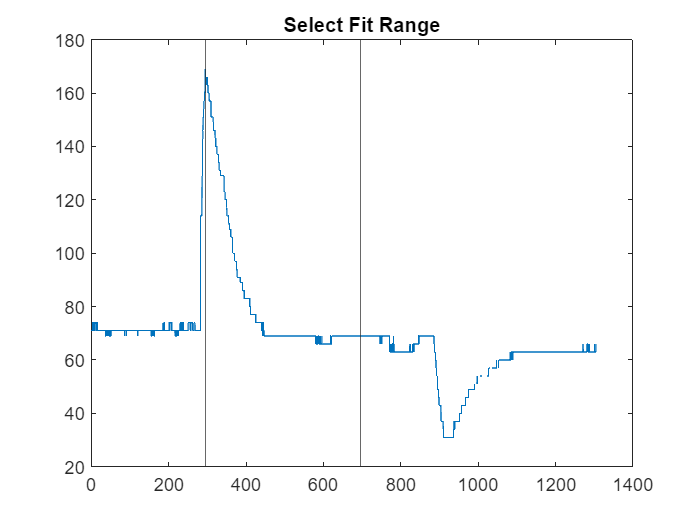

 
close all hidden
fig = figure;
fig.WindowState = "maximized";
plot(centeredTime, normDiameter);
title("Select Fit Range")
for i = 1:3
    dcm_obj = datacursormode(1);
    set(dcm_obj,'DisplayStyle','window',...
    'SnapToDataVertex','off','Enable','on')
    waitforbuttonpress
    c_info{i} = getCursorInfo(dcm_obj);
    dataIndex{i} = c_info{i}.DataIndex;
end
close
clear dcm_obj
plot(centeredTime, normDiameter);
title("Select Fit Range")
xline(c_info{1,2}.Position(1));
xline(c_info{1,3}.Position(1));
hold off

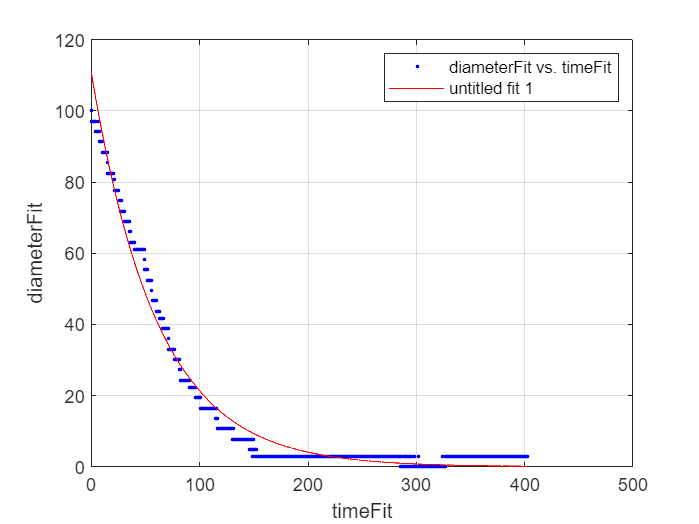

diameterFit = normDiameter(dataIndex{2}:dataIndex{3},:);
diameterFit = 100 * ((diameterFit - min(diameterFit)) / ( max(diameterFit) - min(diameterFit)));
timeFit= centeredTime(dataIndex{2}:dataIndex{3},:);
timeFit = timeFit - timeFit(1);
fig = figure;
[fit, fitInfo] = createFit(timeFit, diameterFit);

append("R²: ", num2str(fitInfo.adjrsquare))

ans = "R²: 0.98445"

tau = log(1/2) / fit.b;
append("Tau1/2: ", num2str(tau),"s")

ans = "Tau1/2: 42.061s"

## Calculate Time To

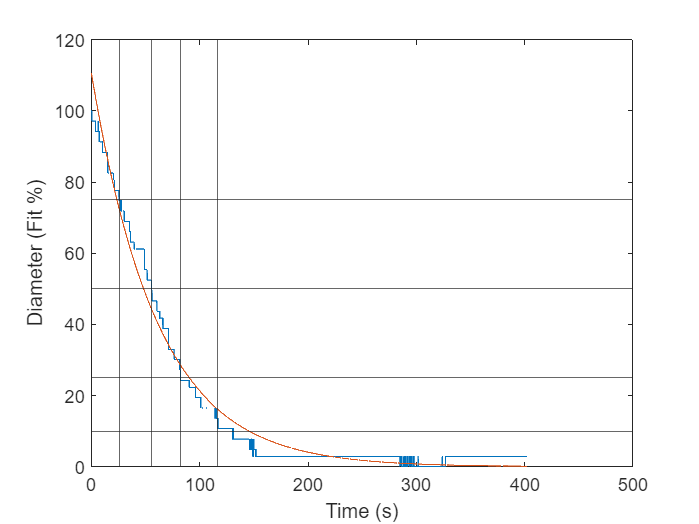

 
close all hidden
timeToVecStr ="25;50;75;90"; %Seperate Values by semicolon ;
splitStr = strsplit(timeToVecStr, ';');
diameterFitted = feval(fit, timeFit);
timeToVec =  100 - arrayfun(@str2num,splitStr);
[~,closestIndex] = min(abs(diameterFit-timeToVec));
timeTo = table(splitStr' , timeFit(closestIndex), 'Variablenames',{'TimeTo' 'time (s)'});
timeToPeak = table("Peak", (centeredTime(dataIndex{2}) - centeredTime(dataIndex{1})), 'Variablenames',{'TimeTo' 'time (s)'});
fig = figure;
plot(timeFit, diameterFit, timeFit, diameterFitted)
ylabel("Diameter (Fit %)");
xlabel("Time (s)");
yline(timeToVec);
xline(timeTo.("time (s)"));

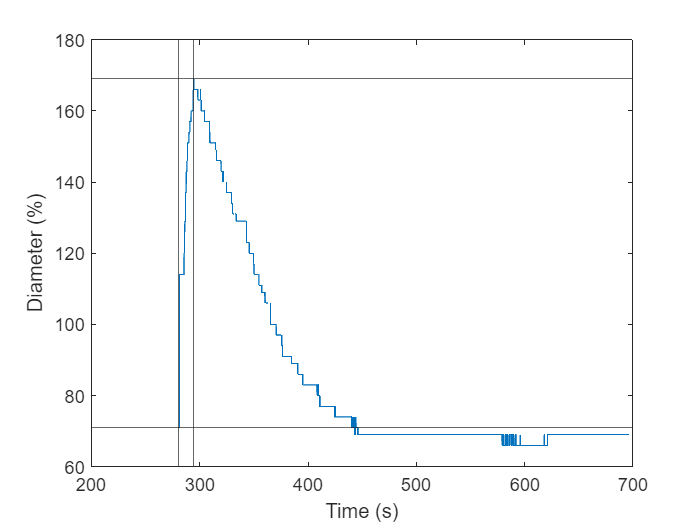

plot(centeredTime(dataIndex{1}:dataIndex{3}), normDiameter(dataIndex{1}:dataIndex{3}))
ylabel("Diameter (%)");
xlabel("Time (s)");
yline(normDiameter([dataIndex{1} dataIndex{2}]));
xline(centeredTime([dataIndex{1} dataIndex{2}]));

timeTo = [timeToPeak; timeTo];
timeTo

timeTo = 5×2 table
    TimeTo    time (s)
    ______    ________

    "Peak"      14.2  
    "25"        25.6  
    "50"        55.4  
    "75"        82.5  
    "90"       116.6  


## Save .Mat

 
[~,name,~] = fileparts(fileName);
[folder, file]  = uiputfile(append(name, ".mat"));
save(fullfile(file,folder))

## Save .csv

 
finDataTable = table(num2str(centeredTime), normDiameter, 'VariableNames', {'Time (s)', 'Outer Diameter (%)'});
finTauTable = table(tau);
finTimeToTable = timeTo;
folder = uigetdir;
[~,name,~] = fileparts(fileName);
writetable(finDataTable, append(folder,"/",name,"_ProcessedKinetic.csv"),'Delimiter',';');
writetable(finTauTable, append(folder,"/",name,"_TauHalf.csv"),'Delimiter',';');
writetable(finTimeToTable, append(folder,"/",name,"_TimeTo.csv"),'Delimiter',';');


## Save .html

 
[filepath,name,ext] = fileparts(fileName);
[folder, file] = uiputfile(append(name,'.html'));
export("Vessel_Kinetik_Analyse.mlx",fullfile(file,folder),Format="html", OpenExportedFile=true, HideCode=true)
